## **Basis:**

simplified model:

front spar + rear spar + skin.

Separate the loading into a force on shear centre(flexural axis) and a torque

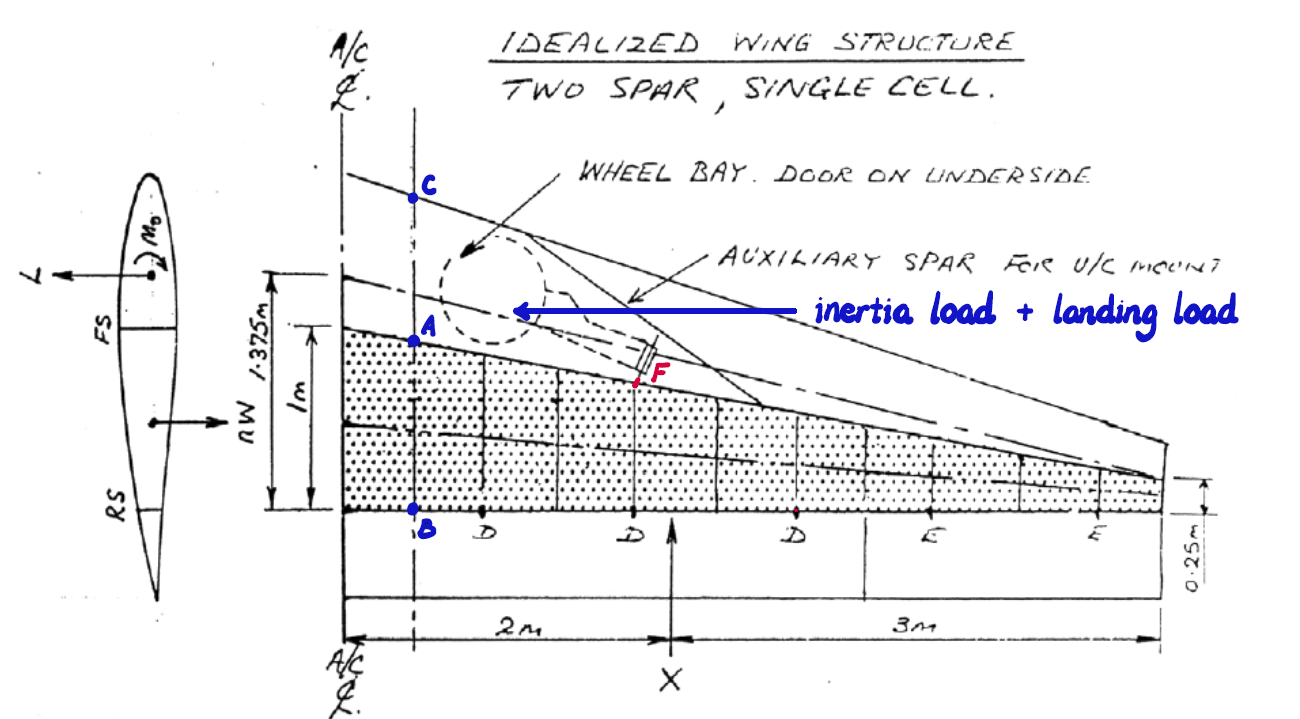

actual model:

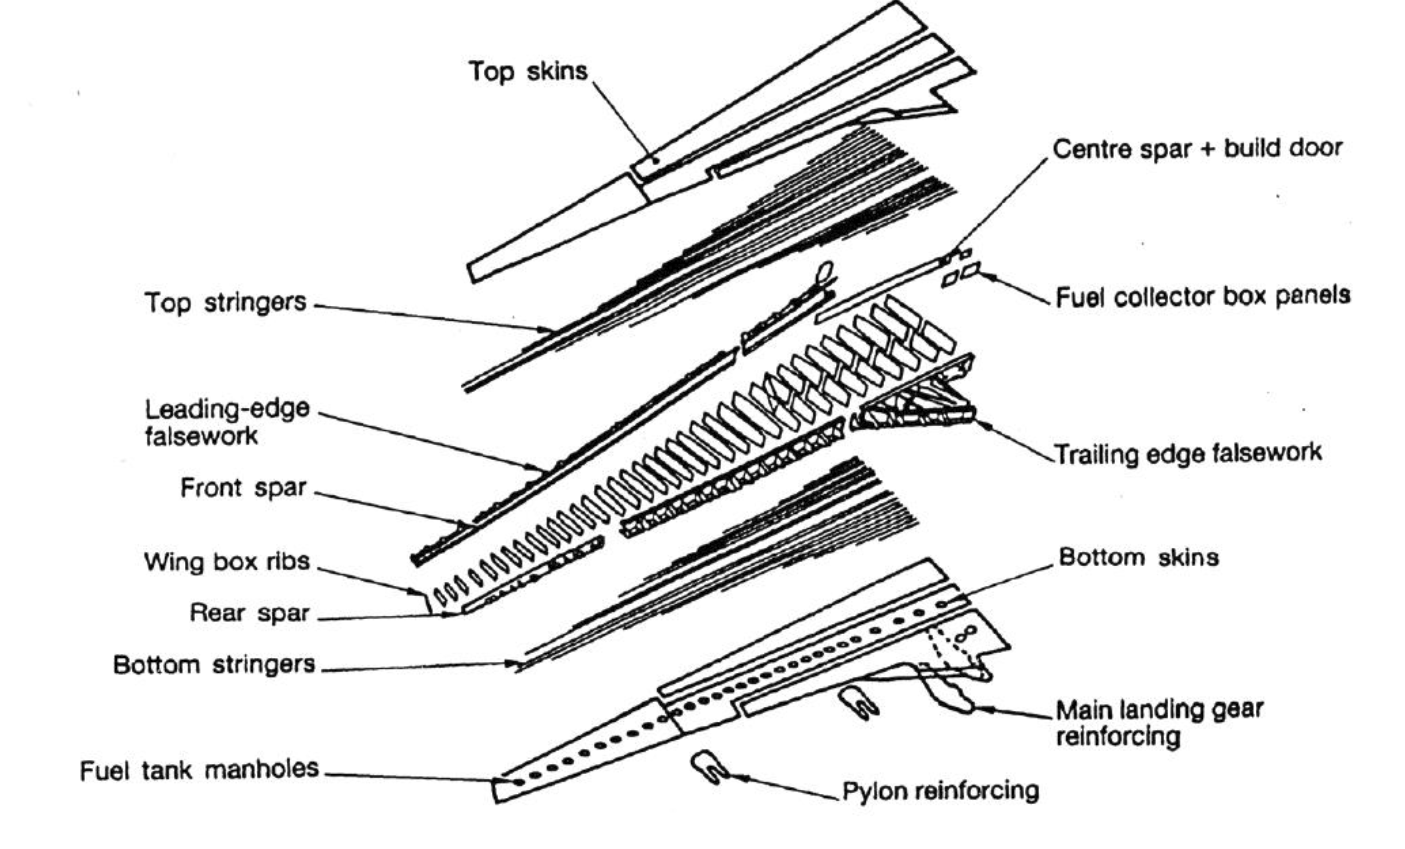

Top surface is under compression, more stringers

Bottom surface is under tension, less stringers

-skin thickness and number of ribs are inversely proportional

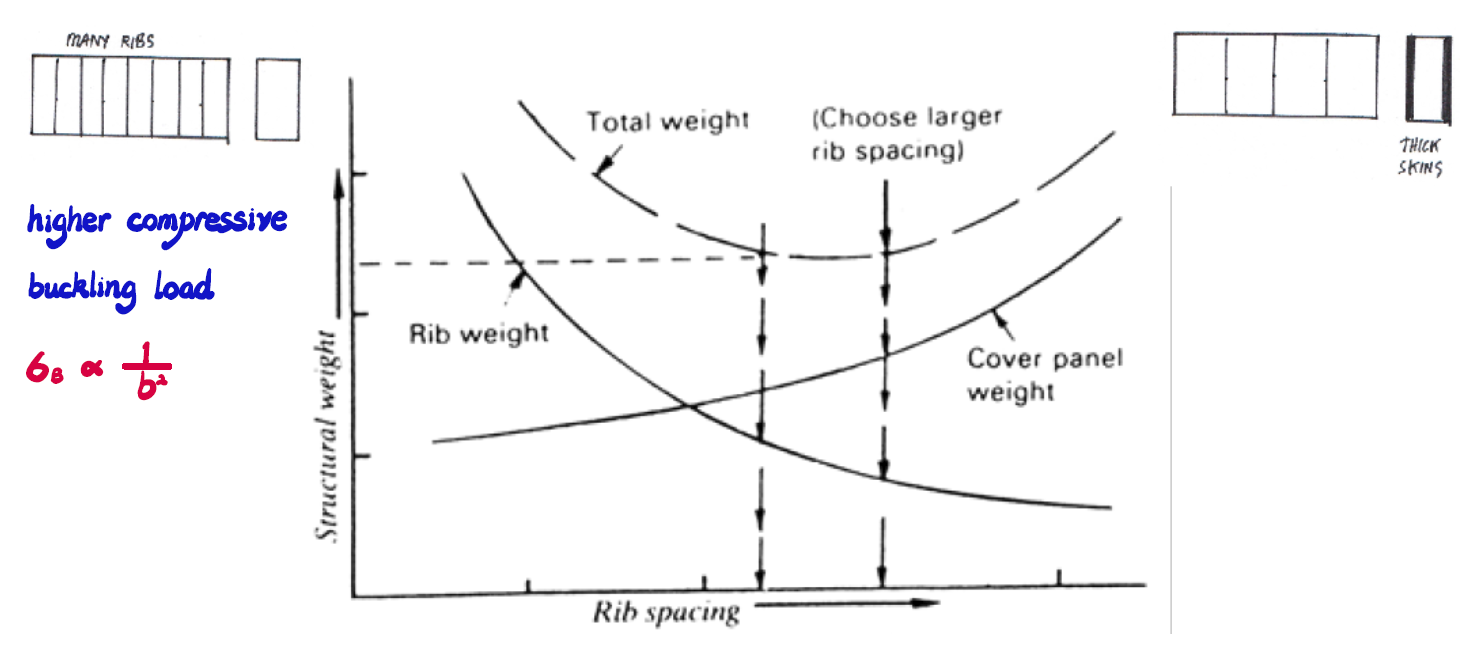

Web:

sine-wave web for composite

metal:

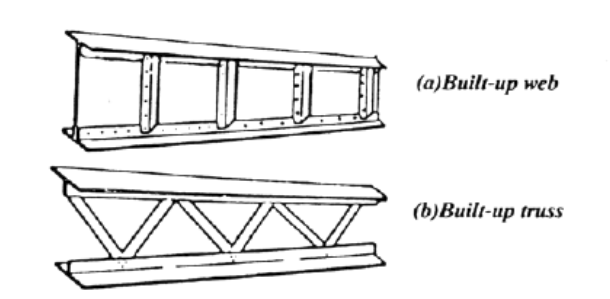

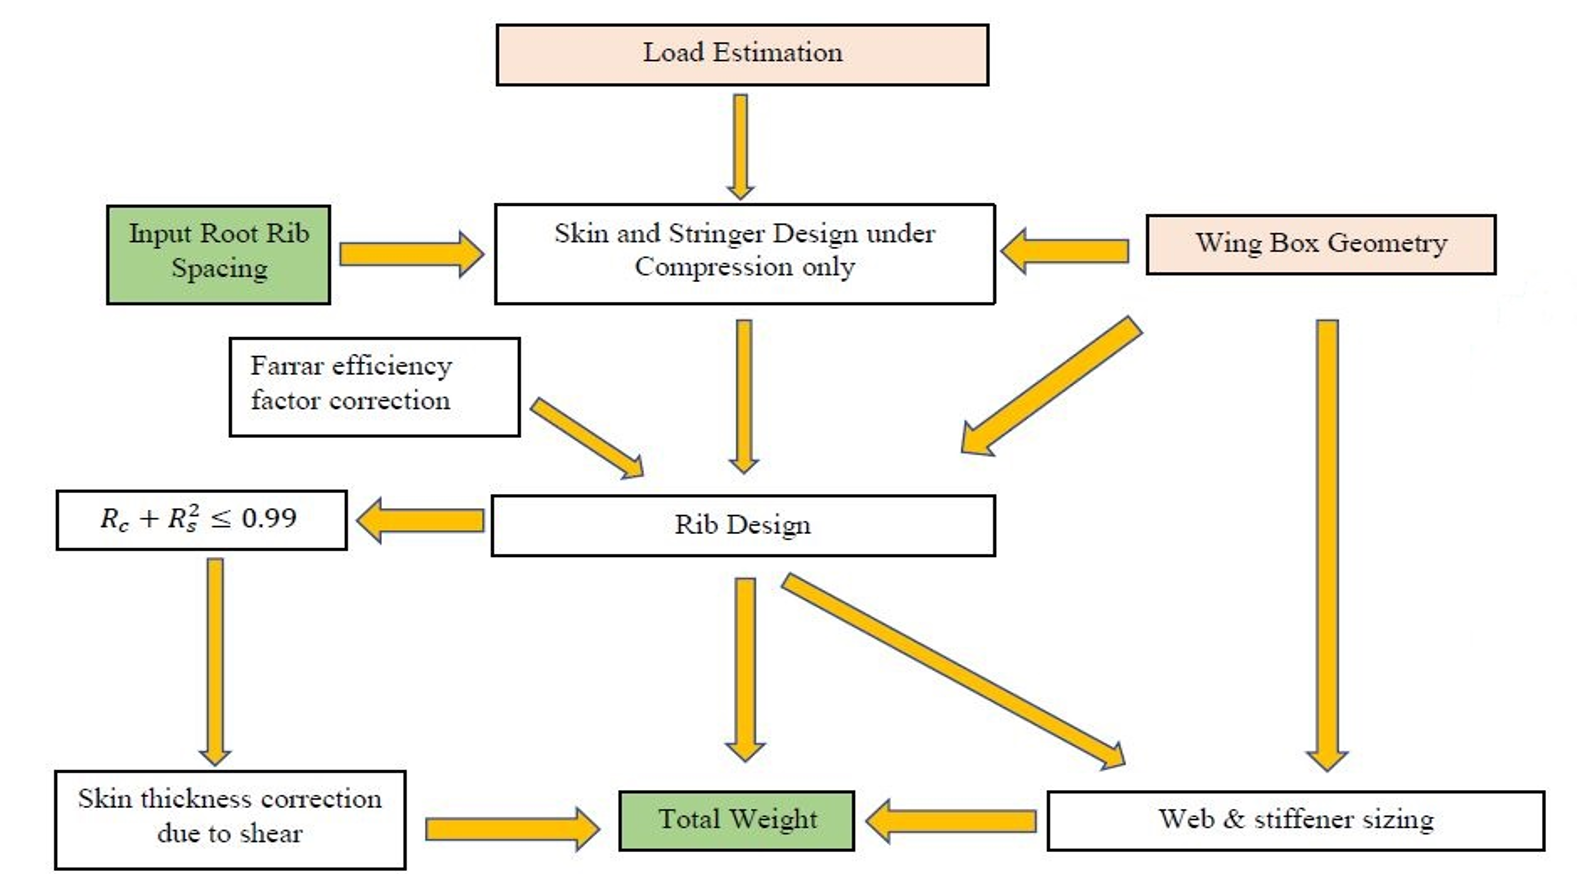

## 1.skin design

sigmacr/sigma0 is from** catchpole diagram**

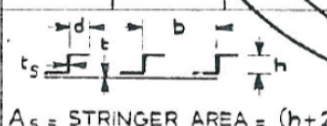

load("airfoil.mat")
load("wing_opt.mat")
load("scr_s0.mat")
load("Farror.mat")
T = readtable("E - Wing Load.xlsx",'Sheet',"Wing Torque");

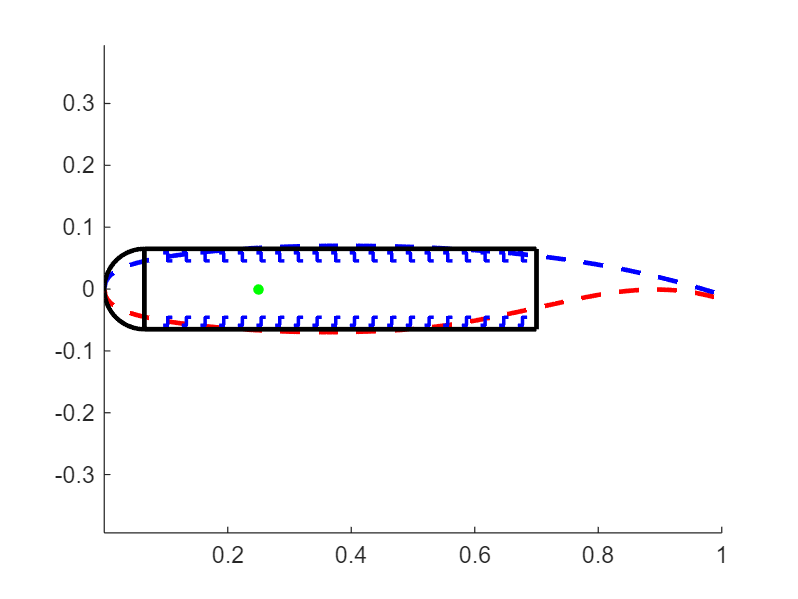

location = table2array(T(1:60,3));
M = table2array(T(1:60,25))*1e-3;

steel=material();
steel.E = 70e9;

wb = wingbox();
%define geometry

wb.b2_c = 0.2;
wb.c_c = 0.7 - wb.b2_c/2;
wb.R1_c = wb.b2_c/2;
wb.R2_c = wb.R1_c;
%define stringers
wb.N = 20;
wb = wb.calcb1();
wb.ts = 10e-3;
wb.hs = 80e-3;
wb.ds = wb.hs*0.3;
wb = wb.calcStringerArea();
wb.t2 = 7.72e-3;
wb.L = 1;


figure(1)
clf;
wb.drawwithAirfoil(airfoil)


display("ts/t2:")

    "ts/t2:"



display(wb.ts/wb.t2)

    1.2953



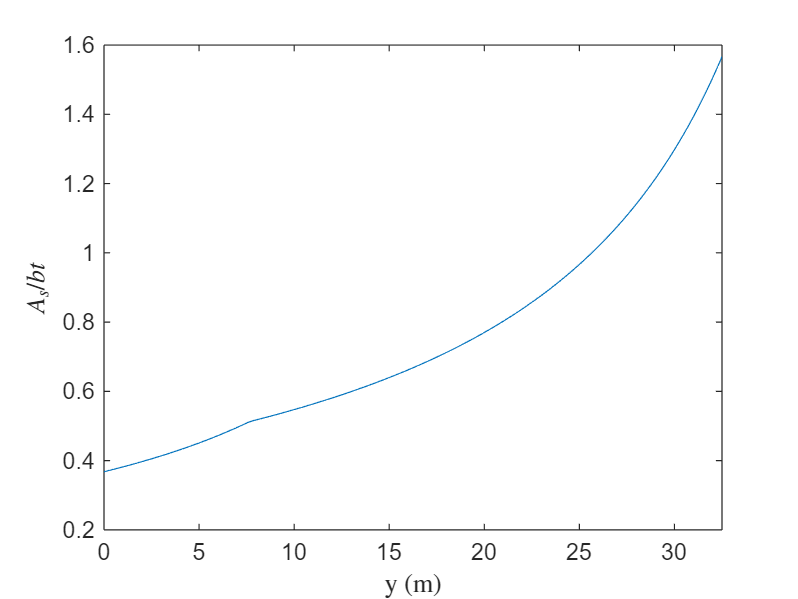


figure(2)
clf;
plot(wing_opt.stripy, wb.As./(wb.b1_c.*wing_opt.cn)./wb.t2)
xlabel("y (m)","Interpreter","latex")
ylabel("$A_s/bt$","Interpreter","latex")
xlim([0 wing_opt.s])

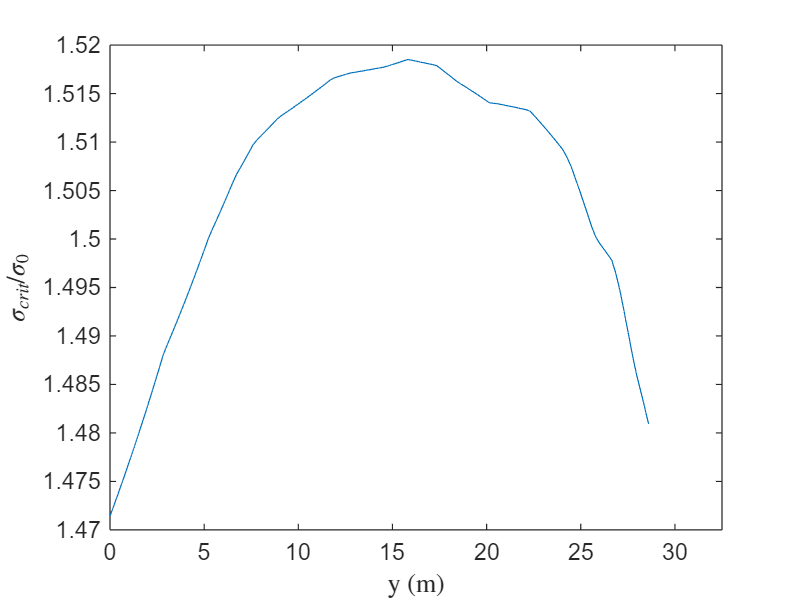

wb = wb.interpsr_s0(digitized_data,wing_opt);
figure(3)
plot(wing_opt.stripy, wb.sr_s0)
xlim([0 wing_opt.s])
xlabel("y (m)","Interpreter","latex")
ylabel("$\sigma_{crit}/\sigma_{0}$","Interpreter","latex")

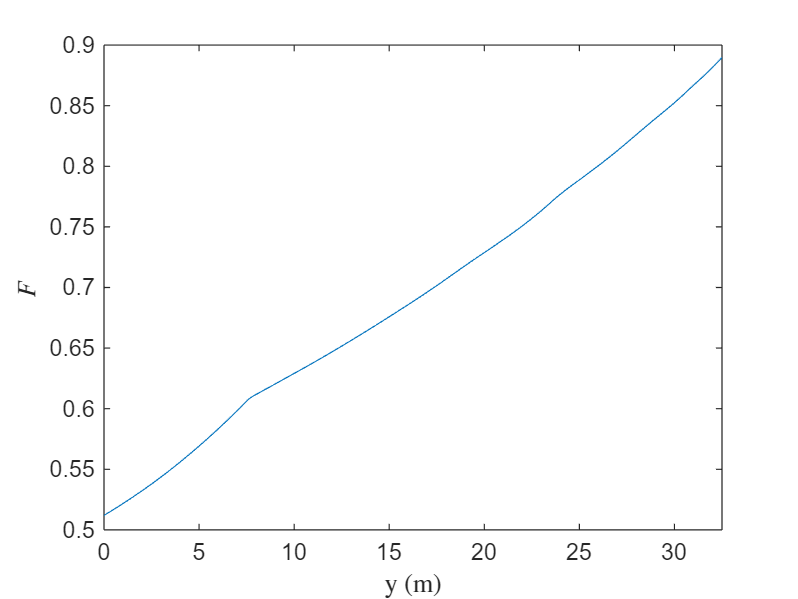


wb = wb.interpretF(F_data, wing_opt);
figure(4)
clf;
plot(wing_opt.stripy, wb.F)
xlim([0 wing_opt.s])
xlabel("y (m)","Interpreter","latex")
ylabel("$F$","Interpreter","latex")


figure(5)
clf;
location = location + 3.2

location =     3.2000
    3.7000
    4.2000
    4.7000
    5.2000
    5.7000
    6.2000
    6.7000
    7.2000
    7.7000



location_full = [-flip(location);location];
M_full = [flip(M);M];
plot(location_full,M_full)
M_new = interp1(location_full, M_full, wing_opt.stripy, 'spline');
hold on
M = M_new

M = 1.0e+04 *

         0    0.0003    0.0018    0.0045    0.0083    0.0131    0.0188    0.0251    0.0319    0.0392    0.0469    0.0552    0.0638    0.0728    0.0822    0.0920    0.1021    0.1126    0.1233    0.1344    0.1458    0.1574    0.1694    0.1816    0.1941    0.2068    0.2198    0.2330    0.2465    0.2602    0.2741    0.2883    0.3027    0.3172    0.3320    0.3470    0.3622    0.3776    0.3932    0.4090    0.4249    0.4411    0.4574    0.4739    0.4906    0.5074    0.5244    0.5415    0.5589    0.5765


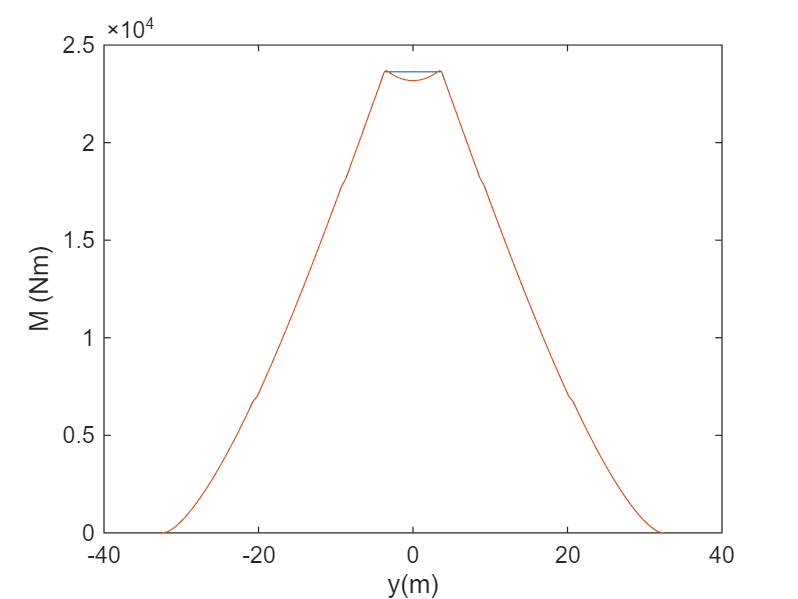

plot(wing_opt.stripy,M)
xlabel("y(m)")
ylabel("M (Nm)")


%critical stress: Euler buckling
%Farror: Local buckling
%They should happen at the same time(optimized) i.e. sigma_cr - sigma_f = 0
sigma_cr = findCricStress(wb,M,wing_opt,steel)

sigma_cr = 1.0e+07 *

       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN       NaN    6.1745    6.0176    5.8666    5.7212    5.5826    5.4499    5.3219    5.1982    5.0779    4.9605    4.8448    4.7330    4.6250    4.5212    4.4219    4.3265    4.2342    4.1448    4.0582    3.9743    3.8924    3.8127    3.7348    3.6592    3.5860    3.5149    3.4459    3.3789    3.3139    3.2507    3.1887    3.1283


sigma_f = findFStress(wb,M,wing_opt,steel)

sigma_f = 1.0e+06 *

         0    0.4121    0.9542    1.4664    1.9557    2.4158    2.8340    3.2079    3.5460    3.8561    4.1426    4.4079    4.6544    4.8841    5.0987    5.2993    5.4871    5.6627    5.8270    5.9810    6.1254    6.2607    6.3878    6.5071    6.6192    6.7249    6.8247    6.9187    7.0075    7.0913    7.1704    7.2449    7.3153    7.3816    7.4440    7.5027    7.5577    7.6089    7.6561    7.6994    7.7386    7.7733    7.8037    7.8322    7.8590    7.8840    7.9072    7.9289    7.9499    7.9695


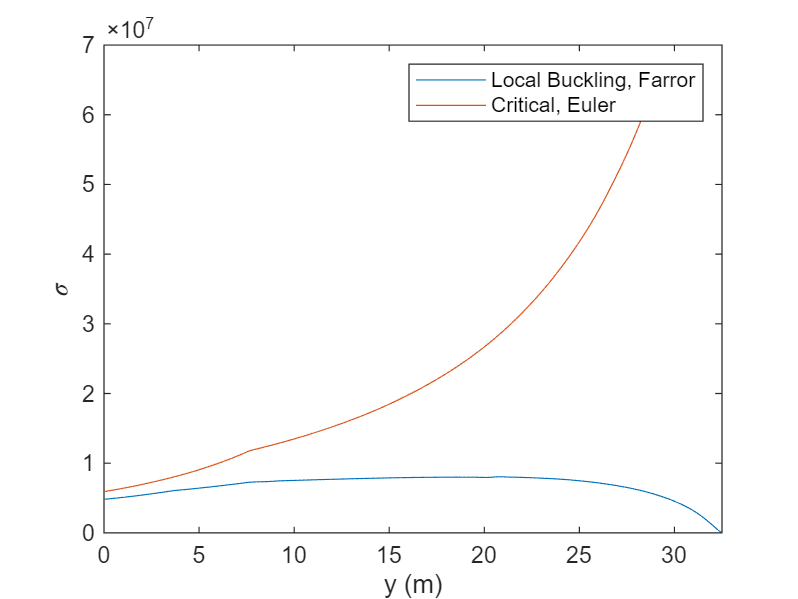

figure(6)
clf;
plot(wing_opt.stripy, sigma_f);
hold on
plot(wing_opt.stripy, sigma_cr);
legend("Local Buckling, Farror","Critical, Euler")
xlabel("y (m)")
ylabel("$\sigma$","Interpreter","latex")
xlim([0 wing_opt.s])